clear

## System Identification

% 1. By trial and error  
% 2. Use script functions
% 3. Use System identification toolbox

## Load Fan Data

FanDynData = load('FanDynData.txt');
Time = FanDynData(1,:)'; Ts = Time(2)-Time(1);
input =FanDynData(2,:)';
output = FanDynData(3,:)';
data = iddata(output,input,Ts);
plot(data,'r')

## System Identification

sysTF = tfest(data,1,0) % estimate transfer function

s = tf('s'); % define laplace operator s
sys = sysTF*exp(-s); % add time delay to transfer function
[y,t] = step(10*sys,10); % simulate response for 10 seconds

figure
plot(Time,output,'r') % plot measured output
hold on
plot(t, squeeze(y),'k', 'LineWidth',2)
grid on

xlabel('Time [s]')
ylabel('Thrust [N]')
legend('Measured Data','Simulated Response')


## Denoise Data

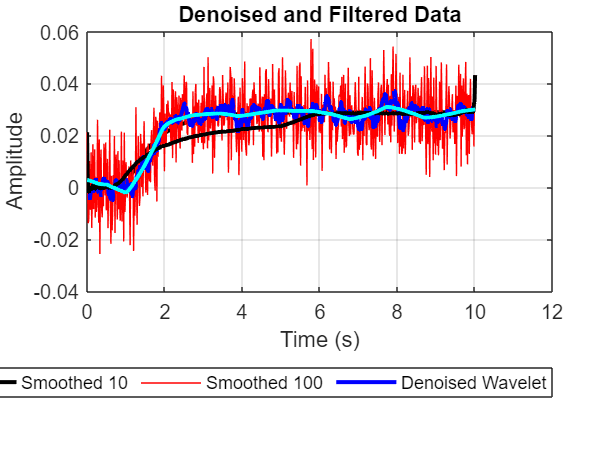

% 
ResponseFilter = smooth(output,10); % moving average filter - buffer length 10
ResponseFilter2 = smooth(output,1000); % moving average filter - buffer length 100
% 
plot(Time,output,'r')
hold on
grid on
plot(Time,ResponseFilter,'b','LineWidth',2)
plot(Time,ResponseFilter2,'k','LineWidth',2)
% xlabel('Time (s)'),ylabel('Amplitude'),title('Denoised and Filtered Data')
% legend('Raw Data','Smoothed 10','Smoothed 100',Location='southoutside',Orientation='horizontal')

output1 = wdenoise(output, 6, ...
    'Wavelet', 'sym4', ...
    'DenoisingMethod', 'Bayes', ...
    'ThresholdRule', 'Median', ...
    'NoiseEstimate', 'LevelIndependent');

% 
plot(Time,output1,'c','linewidth',2)
legend('Raw Data','Smoothed 10','Smoothed 100','Denoised Wavelet',Location='southoutside',Orientation='horizontal')